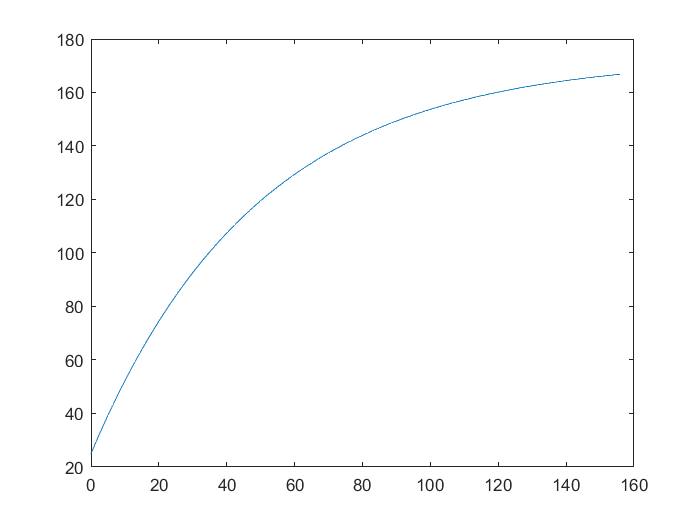

clear
lamada=0.0259;v=18.1*10^(-6);pr=0.703;miu=7/600;l=0.2;
h0=(lamada*0.664*sqrt(miu*l/v)*pr^(1/3))/l;
a=2328*703*7.5*10^(-5)/2.5;
T11=0:0.5:156;T01=T11(1);t01=25+273;t11=173+273;
t1=t11-exp((T01-T11)/a+log(t11-t01))-273;
plot(T11,t1)

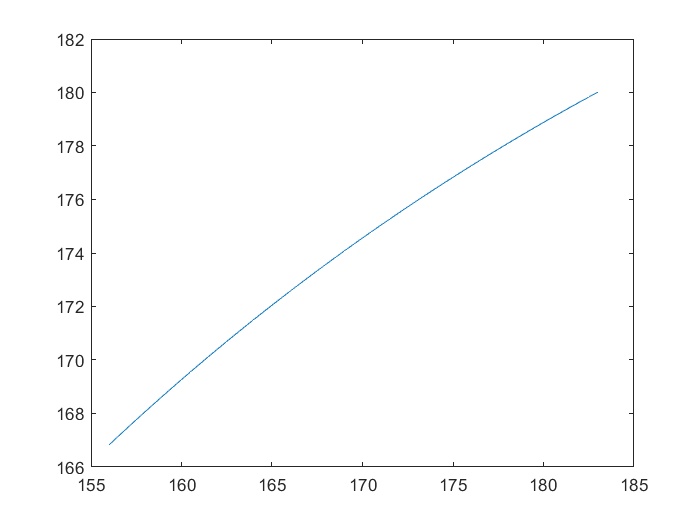

T12=156:0.5:183;T02=T12(1);t02=t1(end)+273;t12=198+273;
t2=t12-exp((T02-T12)/a+log(t12-t02))-273;
plot(T12,t2)

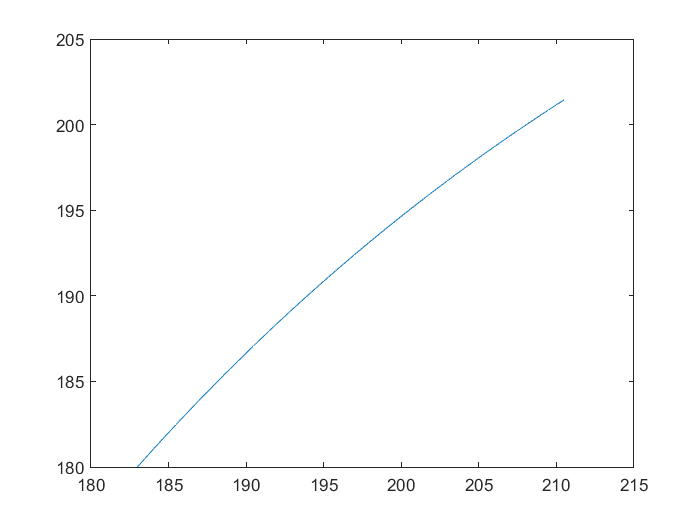

T13=183:0.5:210.5;T03=T13(1);t03=t2(end)+273;t13=230+273;
t3=t13-exp((T03-T13)/a+log(t13-t03))-273;
plot(T13,t3)

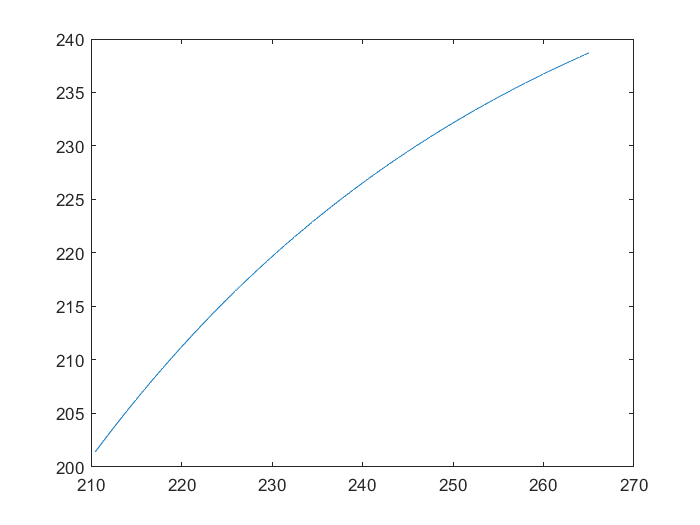

T14=210.5:0.5:265;T04=T14(1);t04=t3(end)+273;t14=257+273;
t4=t14-exp((T04-T14)/a+log(t14-t04))-273;
plot(T14,t4)

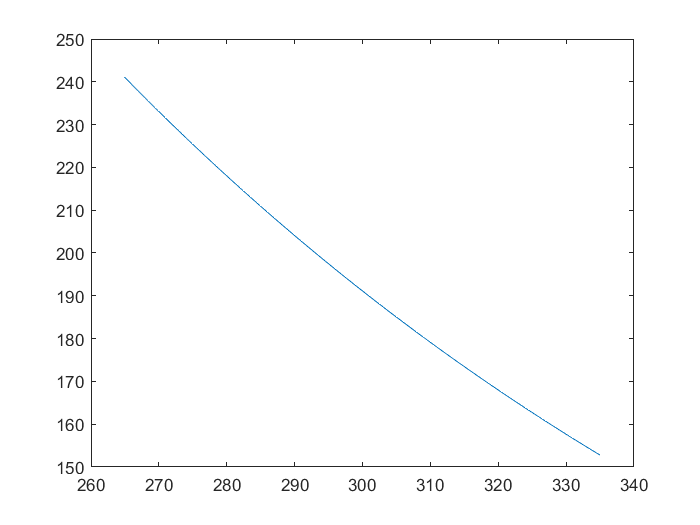

T15=265:0.5:335;len=length(T15);T05=T15(1);t05=t4(end)+273;t15=-111/35*T15+7682/7;
t5=25+216*exp(-0.0075*(T15-T05));
plot(T15,t5)

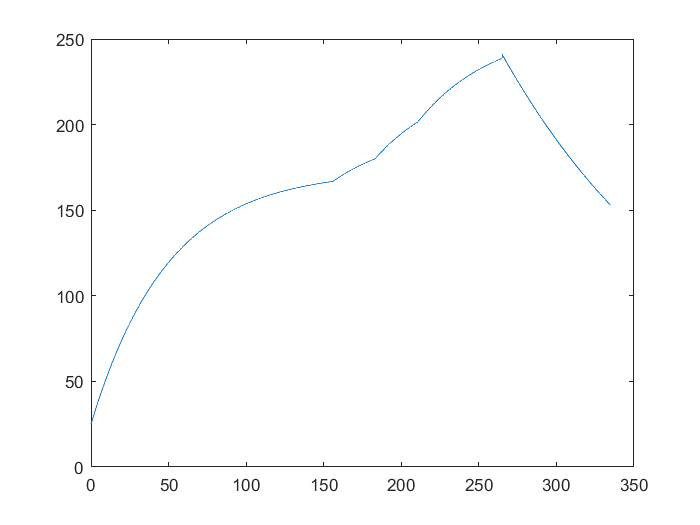

plot([T11,T12,T13,T14,T15],[t1,t2,t3,t4,t5])

my=[[T11,T12,T13,T14,T15]',[t1,t2,t3,t4,t5]'];